%  sat4_main.m
 clear; clc; close all; 

%% ---------- 0) параметры реакционных колес ----------
reaction_wheel_params4;     % создаёт: B, Bplus, tau_max, Jr, IrR_local, …

disp('B = ');

B = 


disp(B);

    0.5774    0.5774   -0.5774   -0.5774
    0.5774   -0.5774    0.5774   -0.5774
    0.5774   -0.5774   -0.5774    0.5774



fprintf('— нули в строках roll/pitch? если да – махи вообще не дают момент по этим осям.\n');

— нули в строках roll/pitch? если да – махи вообще не дают момент по этим осям.


%% 2) Небольшое смещение: поворот оси rw4 на пару градусов
angle_deg = 3; % поворот на 3°
angle_rad = deg2rad(angle_deg);
% Ось вращения: возьмём, например, произвольно [1 1 0] (нормируем)
u = [1 1 0] / norm([1 1 0]);

% Матрица поворота Rodrigues (3×3)
K = [   0, -u(3),  u(2);
      u(3),    0, -u(1);
     -u(2),  u(1),   0 ];
R = eye(3) + sin(angle_rad)*K + (1-cos(angle_rad))*K*K;

% Применяем поворот только к 4-й колонке B (rw4)
B_pert = B;
B_pert(:,4) = R * B(:,4)

B_pert =     0.5774    0.5774   -0.5774   -0.5560
    0.5774   -0.5774    0.5774   -0.5987
    0.5774   -0.5774   -0.5774    0.5766


% затем заново нормируем все колонки (вдруг чуть ушли по длине)
for i = 1:4
    B_pert(:,i) = B_pert(:,i) / norm(B_pert(:,i));
end
disp(B_pert);

    0.5774    0.5774   -0.5774   -0.5560
    0.5774   -0.5774    0.5774   -0.5987
    0.5774   -0.5774   -0.5774    0.5766




%%% ---------- 1) параметры КА (корпус + 4 колеса) ----------
ms = 2.6;                    % масса КА, кг
lx = 0.10; ly = 0.10; lz = 0.20;   % габариты, м

Is = (ms/12) * diag([ly^2+lz^2, lx^2+lz^2, lx^2+ly^2]);  % корпус
I  = Is + 4*IrR_local;        % + 4 одинаковых колеса, грубо
invI = inv(I);
disp('Is ='); disp(Is);

Is =
    0.0108         0         0
         0    0.0108         0
         0         0    0.0043



disp('I ='); disp(I);

I =
    0.0113         0         0
         0    0.0111         0
         0         0    0.0046



s = svd(B);
sigma_min = s(end);
M_test = [5e-3;0;0];

%% ---------- 2) начальное состояние ----------
omega0     = deg2rad([ 0;  0; 0]);   % рад/с
% omega0     = [ 0.5; 0; 0; ];   % рад/с
q0         = [1; 0; 0; 0];            % без поворота
omega_rw0  = zeros(4,1);              % скорости колес
x0 = [omega0; q0; omega_rw0];         % 3+4+4 = 11×1


%% ---------- 3) регулятор и целевая ориентация ----------
Ix = I(1,1);  Iy = I(2,2);  Iz = I(3,3);

% требования
Ts = 50;      % с
zeta = 0.8;

wn = 4 / (zeta * Ts);     % общая частота

% коэффициенты
Kp_x = Ix * wn^2;
Kd_x = 2 * zeta * wn * Ix;

Kp_y = Iy * wn^2;
Kd_y = 2 * zeta * wn * Iy;

Kp_z = Iz * wn^2;
Kd_z = 2 * zeta * wn * Iz;

  Kp = diag([0, 0, 0]);
  Kd = diag([0, 0, 0]);
% Kp = diag([1.25e-5 1.23e-5 5.087e-6]);
% Kd = diag([7.52e-4 7.385e-4 3.052e-4]);



eul = deg2rad([0,0,0]);
q_des = eul2quat(eul,'ZYX').';   % вернёт 1×4, транспонируем в 4×1

M_dist = [5e-6;0;0;];                   % возмущающий момент, Н·м
use_tikh = 0; 
pars.lambda = 0;
pars.fail_idx = [];  % индекс маховика, выходящего из строя
pars.t_fail  = []; % время отказа
pars.I       = I;
pars.invI    = invI;
pars.Kp      = Kp;
pars.Kd      = Kd;
pars.q_des   = q_des;
pars.B       = B;                     % 3×4
pars.Bplus   = Bplus;                 % 4×3
pars.tau_max = tau_max;
pars.Jr      = Jr;                    % скаляр
pars.M_dist  = M_dist;
pars.omega_lim = 600;
if use_tikh
pars.alloc      = @(T) ridge_alloc(T, pars.B,      pars.lambda);
pars.alloc_free = @(T,Bf) ridge_alloc(T, Bf,        pars.lambda);
else
    pars.alloc = @(T) pinv(pars.B) * T;
    pars.alloc_free = @(T,Bf) pinv(Bf)*T;
end

%% ---------- 6) интегрирование ODE ----------
tspan = [0 500];
opts  = odeset('MaxStep', 0.1);

global log_tau log_t idx log_omega_s
idx = []; log_tau = []; log_t = []; log_omega_s = [];
[t, x] = ode45(@(t,x) rhs_attitude4(t, x, pars), tspan, x0, opts);

Time = 0.00 s
Time = 5.02 s
Time = 10.03 s
Time = 15.08 s
Time = 20.08 s
Time = 25.08 s
Time = 30.08 s
Time = 35.08 s
Time = 40.08 s
Time = 45.08 s
Time = 50.08 s
Time = 55.08 s
Time = 60.08 s
Time = 65.08 s
Time = 70.09 s
Time = 75.10 s
Time = 80.12 s
Time = 85.13 s
Time = 90.18 s
Time = 95.19 s
Time = 100.20 s
Time = 105.22 s
Time = 110.23 s
Time = 115.28 s
Time = 120.29 s
Time = 125.30 s
Time = 130.32 s
Time = 135.33 s
Time = 140.38 s
Time = 145.39 s
Time = 150.40 s
Time = 155.42 s
Time = 160.43 s
Time = 165.48 s
Time = 170.49 s
Time = 175.50 s
Time = 180.52 s
Time = 185.53 s
Time = 190.58 s
Time = 195.59 s
Time = 200.60 s
Time = 205.62 s
Time = 210.63 s
Time = 215.68 s
Time = 220.69 s
Time = 225.70 s
Time = 230.72 s
Time = 235.73 s
Time = 240.78 s
Time = 245.79 s
Time = 250.80 s
Time = 255.82 s
Time = 260.82 s
Time = 265.82 s
Time = 270.82 s
Time = 275.82 s
Time = 280.82 s
Time = 285.82 s
Time = 290.82 s
Time = 295.82 s
Time = 300.82 s
Time = 305.82 s
Time = 310.82 s
Time = 315.82 

omega_rw = x(:,8:11);

statePic = 1

statePic = 1

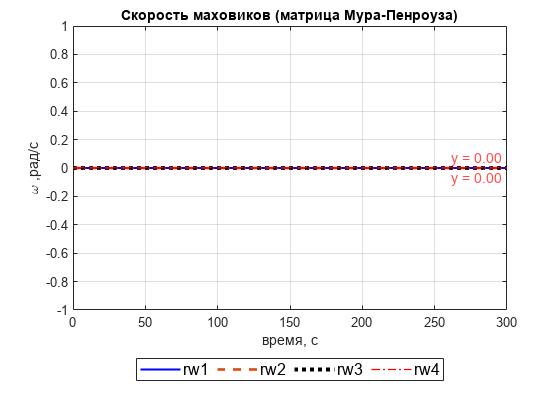

figure;
h = plot(t,omega_rw);
maxLine = max(omega_rw(:,1));
minLine = min(omega_rw(:,3));
labelText = sprintf('y = %.2f', maxLine);
h1 = yline(maxLine, 'r--', labelText, 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom', 'FontSize',11);
labelText = sprintf('y = %.2f', minLine);
h2 = yline(minLine, 'r--', labelText, 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'top', 'FontSize',11);
legend('rw1','rw2','rw3','rw4','Location','southoutside', ...
       'Orientation','horizontal','FontSize', 12); xlabel('время, с'); ylabel('\omega ,рад/с'); grid on;
title("Скорость маховиков (матрица Мура-Пенроуза)")
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % r1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % r2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % r3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % r4
xlim([0 300])
filename = statePic + "Скорость маховиков (матрица Мура-Пенроуза) " +'.png';
print(gcf, filename, '-dpng', '-r300');

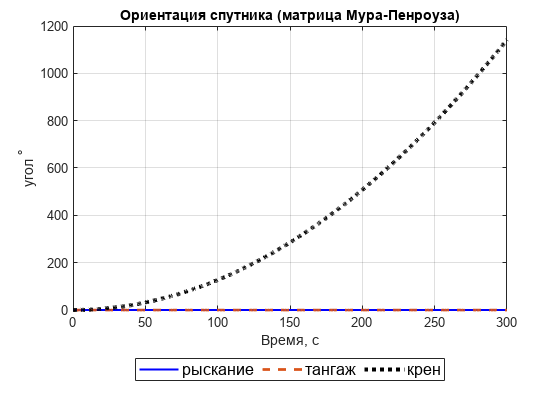


q = x(:,4:7);
q = q./vecnorm(q,2,2);
euler = zeros(length(t),3);
% --- кватернионы -> углы Эйлера (градусы) ---
euler_deg = zeros(length(t),3);
for k = 1:length(t)
    R = quat2rotm(q(k,:));
    euler_deg(k,:) = rad2deg( rotm2eul(R,'ZYX') );
end
% --- делаем непрерывными и возвращаем в градусы ---
euler_cont = rad2deg( unwrap( deg2rad(euler_deg), [], 1) );  % 3 столбца
 ind = find(euler_cont(:,3) > 49.5, 1, 'first');
 stop = t(ind);
figure;
h = plot(t, euler_cont.');      % 3×N  (правильное имя!)
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % yaw
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % pitch
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % roll
legend({'рыскание','тангаж','крен'}, ...
       'Location','southoutside', ...
       'Orientation','horizontal','FontSize', 12);
 xlabel('Время, с','FontSize', 11); ylabel('угол ^\circ','FontSize', 11);
 title("Ориентация спутника (матрица Мура-Пенроуза)")
%   h1 = xline(stop, 'r--', 'Манёвр завершён', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom', 'FontSize',11);
  y_limits = ylim;
% y_center = mean(y_limits);  % центр по вертикали
%   text(stop, y_center, sprintf('t = %.2f с', stop), ...
%     'Rotation', 90, ...
%     'VerticalAlignment', 'top', ...
%     'HorizontalAlignment', 'center', ...
%     'FontSize', 12, ...
%     'Color', 'r');
%   set(get(get(h1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
grid on
filename = statePic + "Ориентация спутника (матрица Мура-Пенроуза) "+ '.png';
print(gcf, filename, '-dpng', '-r300');
xlim([0 300])

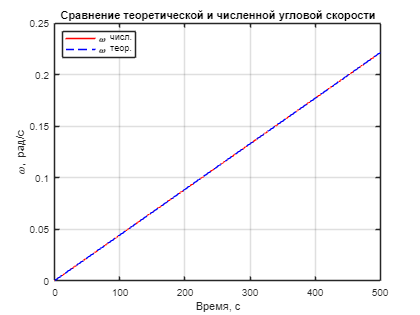


% Теоретическая угловая скорость
ww_teor = (M_dist(1) / I(1,1)) * t;

% Численно полученная угловая скорость из данных ориентации
dt = diff(t); 
theta = deg2rad(euler_cont(:,3));  
dtheta = diff(theta); 
ww = dtheta ./ dt;  % длина N-1

% Усреднённый вектор времени для ww
t_mid = t(1:end-1) + dt/2;

% Построение
figure;
plot(t_mid, ww, 'r', 'DisplayName', '\omega числ.'); hold on;
plot(t, ww_teor, 'b--', 'DisplayName', '\omega теор.');
grid on;
xlabel('Время, с');
ylabel('\omega, рад/с');
legend('Location', 'northwest');
title('Сравнение теоретической и численной угловой скорости');


d = (abs(ww-ww_teor(1:length(ww))))

d = 1.0e-05 *

    0.5535
    0.5535
    0.5535
    0.5535
    0.5535
    0.5535
    0.5535
    0.5535
    0.5535
    0.5535


(ww(2255)-ww_teor(2255))/ww_teor(2255) * 100

ans = 0.0222

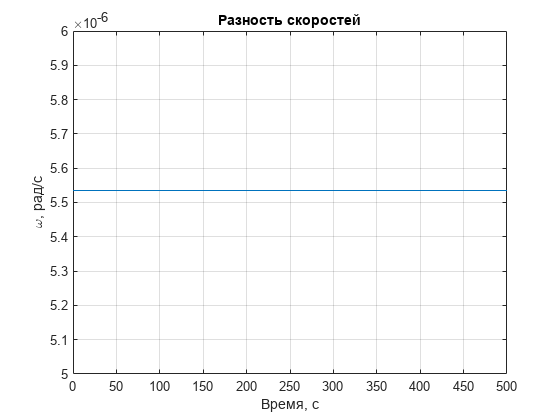



figure
plot(t(1:length(d)), d)
ylim([5e-6 6e-6])
grid on
xlabel('Время, с');
ylabel('\omega, рад/с');

title('Разность скоростей');

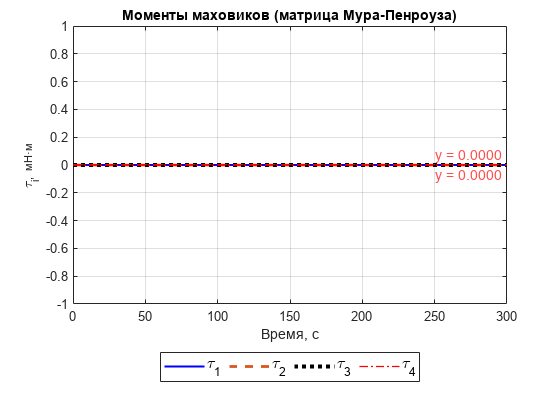


tau_x = log_tau;
k = idx-1;                        % фактическое число записей

maxLine = tau_x(1,1)*1e3;
minLine = tau_x(4,1)*1e3;

figure; 
h = plot(log_t(1:k), 1e3*tau_x(:,1:k).');
xlabel('Время, с');  ylabel('\tau_i,  мН·м');
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % tau1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % tau2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % tau3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % tau4
title("Моменты маховиков (матрица Мура-Пенроуза)")

labelText = sprintf('y = %.4f', maxLine);
h1 = yline(maxLine, 'r--', labelText, 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom', 'FontSize',11);
labelText = sprintf('y = %.4f', minLine);
h2 = yline(minLine, 'r--', labelText, 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'top', 'FontSize',11);
% Убрать из легенды
set(get(get(h1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');


legend('\tau_1','\tau_2','\tau_3','\tau_4','Location','southoutside', 'Orientation','horizontal','FontSize', 12);
grid on;
xlim([0 300])

filename = statePic + "Моменты маховиков (матрица Мура-Пенроуза) "+ '.png';
print(gcf, filename, '-dpng', '-r300');



idx = []; log_tau = []; log_t = []; log_omega_s = [];
use_tikh = 1; 
pars.lambda = 0.5;
pars.alloc      = @(T) ridge_alloc(T, pars.B,      pars.lambda);
pars.alloc_free = @(T,Bf) ridge_alloc(T, Bf,        pars.lambda);
[tt, xx] = ode45(@(t,x) rhs_attitude4(t, x, pars), tspan, x0, opts);

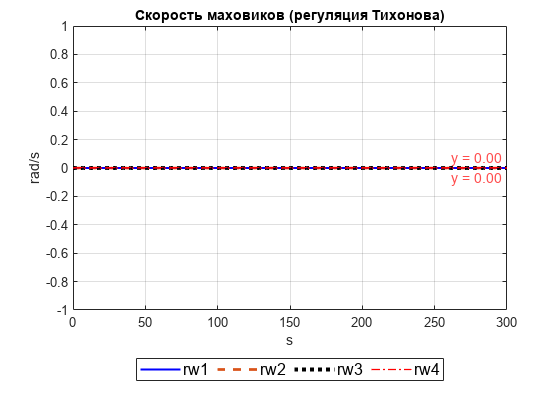


omega_rw_xx = xx(:,8:11);

figure;
h = plot(tt,omega_rw_xx);
maxLine = max(omega_rw_xx(:,1));
minLine = min(omega_rw_xx(:,3));
labelText = sprintf('y = %.2f', maxLine);
h1 = yline(maxLine, 'r--', labelText, 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom', 'FontSize',11);
labelText = sprintf('y = %.2f', minLine);
h2 = yline(minLine, 'r--', labelText, 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'top', 'FontSize',11);
% Убрать из легенды
set(get(get(h1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
legend('\tau_1','\tau_2','\tau_3','\tau_4','Location','southoutside', 'Orientation','horizontal','FontSize', 12);

legend('rw1','rw2','rw3','rw4','Location','southoutside', ...
       'Orientation','horizontal','FontSize', 12); xlabel('s'); ylabel('rad/s'); grid on;
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % r1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % r2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % r3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % r4
title("Скорость маховиков (регуляция Тихонова)")
xlim([0 300])
filename = statePic + "Скорость маховиков (регуляция Тихонова)"+ '.png';
print(gcf, filename, '-dpng', '-r300');

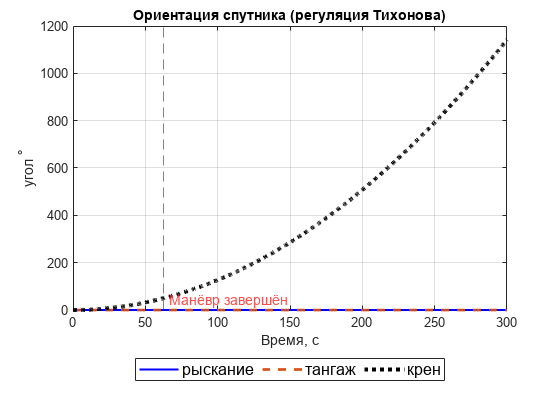



q = xx(:,4:7);
q = q./vecnorm(q,2,2);
euler = zeros(length(t),3);
% --- кватернионы -> углы Эйлера (градусы) ---
euler_deg = zeros(length(t),3);
for k = 1:length(tt)
    R = quat2rotm(q(k,:));
    euler_deg(k,:) = rad2deg( rotm2eul(R,'ZYX') );
end
% --- делаем непрерывными и возвращаем в градусы ---
euler_cont = rad2deg( unwrap( deg2rad(euler_deg), [], 1) );  % 3 столбца
ind = find(euler_cont(:,3) > 49.9, 1, 'first');
stop = t(ind);
figure;
h = plot(t, euler_cont.');      % 3×N  (правильное имя!)
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % yaw
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % pitch
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % roll
h1 = xline(stop, 'r--', 'Манёвр завершён', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom', 'FontSize',11);
  y_limits = ylim;
y_center = mean(y_limits);  % центр по вертикали
  text(stop, y_center, sprintf('t = %.2f с', stop), ...
    'Rotation', 90, ...
    'VerticalAlignment', 'top', ...
    'HorizontalAlignment', 'center', ...
    'FontSize', 12, ...
    'Color', 'r');
  set(get(get(h1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
legend({'рыскание','тангаж','крен'}, ...
       'Location','southoutside', ...
       'Orientation','horizontal','FontSize', 12);
title("Ориентация спутника (регуляция Тихонова)")
xlabel('Время, с','FontSize', 11); ylabel('угол ^\circ','FontSize', 11);
grid on

xlim([0 300])
filename = statePic + "Ориентация спутника (регуляция Тихонова)"+ '.png';
print(gcf, filename, '-dpng', '-r300');

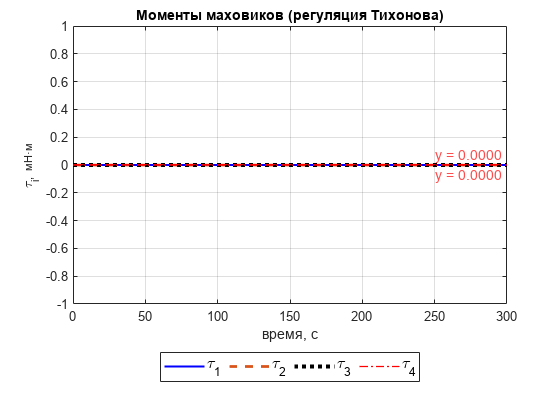




tau_xx = log_tau;
k = idx-1;                        % фактическое число записей
maxLine = tau_xx(1,1)*1e3;
minLine = tau_xx(4,1)*1e3;
figure; 

h = plot(log_t(1:k), 1e3*tau_xx(:,1:k).');
xlabel('время, с');  ylabel('\tau_i,  мН·м');
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % tau1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % tau2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % tau3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % tau4
title("Моменты маховиков (регуляция Тихонова)")


labelText = sprintf('y = %.4f', maxLine);
h1 = yline(maxLine, 'r--', labelText, 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom', 'FontSize',11);
labelText = sprintf('y = %.4f', minLine);
h2 = yline(minLine, 'r--', labelText, 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'top', 'FontSize',11);
% Убрать из легенды
set(get(get(h1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
legend('\tau_1','\tau_2','\tau_3','\tau_4','Location','southoutside', 'Orientation','horizontal','FontSize', 12);
grid on;
xlim([0 300])

filename = statePic + "Моменты маховиков (регуляция Тихонова)"+ '.png';
print(gcf, filename, '-dpng', '-r300');